--- Observer Design Results ---


Gain Margin: 18.89 dB


Phase Margin: 55.99 deg


Closed-Loop Bandwidth: 45.56 rad/s (7.25 Hz)


Closed-loop Poles:


   1.0e+02 *

  -0.8000 + 0.0000i
  -0.6000 + 0.0000i
  -0.0012 + 0.0464i
  -0.0012 - 0.0464i
  -4.0000 + 0.0000i
  -3.0000 + 0.0000i
  -0.0127 + 0.0000i
  -0.0108 + 0.0000i



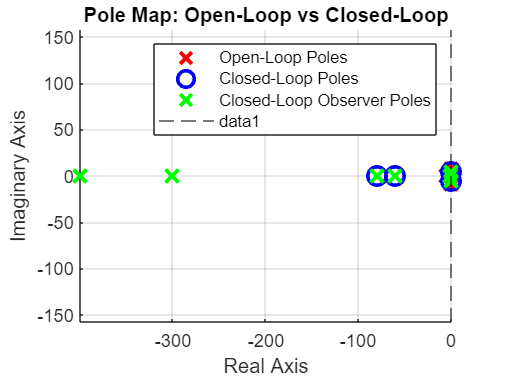

obs_poles(1) = 5*real(closed_loop_poles(1));
obs_poles(2) = 5*real(closed_loop_poles(2));
obs_poles(3) = 10*real(closed_loop_poles(3)) + (0.8*imag(closed_loop_poles(3))*1j);
obs_poles(4) = 10*real(closed_loop_poles(4)) - (0.8*imag(closed_loop_poles(4))1(j^3));

% Design observer gain
L = place(A', C', obs_poles)';
Aobs = A - L*C;

% Combined Observer + Controller System
Acl_obs = [A - B*K,       B*K;
           zeros(size(A)), A - L*C];
B_comb = [B*F;zeros(size(A,1),1)];
C_comb = [C,zeros(1,size(A,1))];
D_comb = D;
sys_obs_cl = ss(Acl_obs, B_comb, C_comb, D);

% --------- Stability Margins ---------
Cl_Tf = tf(sys_obs_cl);
True_State = ss(A - L*C, B, K, 0);    % Controller on true state
State_Correction = ss(A - L*C, L, K, 0);    % Correction via observer
P_analytic = ss(A, B, C, 0);  % Analytical model
Lg_neg_obs = (1/(1+True_State))*State_Correction*P_analytic;

bw_obs = bandwidth(Cl_Tf,-3.05);
[GM_obs,PM_obs] = margin(Lg_neg_obs);
GM_dB_obs = 20*log10(GM_obs);
cl_poles_obs = pole(sys_obs_cl);
info = stepinfo(sys_obs_cl, 'SettlingTimeThreshold', 0.05); % for 5% criterion
settling_time = info.SettlingTime;

fprintf('--- Observer Design Results ---\n');
fprintf('Gain Margin: %.2f dB\n', GM_dB_obs);
fprintf('Phase Margin: %.2f deg\n', PM_obs);
fprintf('Closed-Loop Bandwidth: %.2f rad/s (%.2f Hz)\n', bw_obs, bw_obs/(2*pi));
fprintf('Closed-loop Poles:\n');
disp(cl_poles_obs);
fprintf('5%% Settling Time : %.4f seconds\n', settling_time);


% --------- Read Empirical Data ---------
Emp_Obs_Factor = (1/(1+True_State))*State_Correction;
[mag_emp_obs, phase_emp_obs, freq_emp_obs] = bode(Emp_Obs_Factor,freq_data);
phase_emp_obs = squeeze(phase_emp_obs);
mag_emp_obs = squeeze(mag_emp_obs);
emperical_lg_neg_mag = 10.^(mag_data./20).*mag_emp_obs;
emperical_lg_neg_phase = rad2deg(phase_data) + phase_emp_obs;


% --------- Pole Plot ---------
figure; hold on; grid on; axis equal;
plot(real(open_loop_poles), imag(open_loop_poles), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
plot(real(closed_loop_poles), imag(closed_loop_poles), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
plot(real(cl_poles_obs), imag(cl_poles_obs), 'gx', 'MarkerSize', 10, 'LineWidth', 2);
legend('Open-Loop Poles', 'Closed-Loop Poles', 'Closed-Loop Observer Poles');
xlabel('Real Axis'); ylabel('Imaginary Axis');
title('Pole Map: Open-Loop vs Closed-Loop');
xline(0, '--k');

% --------- Observer Loop Gain Bode Plot with Crossover Markers ---------
[mag_ana_lg, phase_ana_lg, w_ana_lg] = bode(Lg_neg_obs);
mag_ana_lg = squeeze(mag_ana_lg);
phase_ana_lg = squeeze(phase_ana_lg);

Font_Size = 12;

% Convert magnitude to dB
mag_ana_dB = 20*log10(mag_ana_lg);

% ---- Interpolate Gain Crossover Frequency (0 dB magnitude) ----
mag_diff = mag_ana_dB - 0;
idx_gc = find(mag_diff(1:end-1) .* mag_diff(2:end) < 0, 1); % first sign change
if ~isempty(idx_gc)
    wcg = interp1(mag_ana_dB(idx_gc:idx_gc+1), w_ana_lg(idx_gc:idx_gc+1), 0);
else
    wcg = NaN;
end

% ---- Interpolate Phase Crossover Frequency (-180 deg phase) ----
phase_diff = phase_ana_lg + 180;
idx_pc = find(phase_diff(1:end-1) .* phase_diff(2:end) < 0, 1); % first sign change
if ~isempty(idx_pc)
    wcp = interp1(phase_ana_lg(idx_pc:idx_pc+1), w_ana_lg(idx_pc:idx_pc+1), -180);
else
    wcp = NaN;
end

% --------- Plotting ---------
figure;
set(gcf, 'Position', [100, 100, 500, 400]);

% ----- Magnitude Plot -----
subplot(2,1,1);
semilogx(w_ana_lg, mag_ana_dB, 'b', 'LineWidth', 2); hold on;
yline(0, 'k--', 'LineWidth', 1.2);
if ~isnan(wcg)
    xline(wcg, 'm--', 'LineWidth', 1.5, 'Label', sprintf('Gain Crossover = %.2f rad/s', wcg), 'LabelVerticalAlignment', 'bottom');
end
xlabel('Frequency (rad/s)', 'FontSize', Font_Size);
ylabel('Magnitude (dB)', 'FontSize', Font_Size);
title('Observer Loop Gain - Magnitude', 'FontSize', Font_Size);
grid on;

% ----- Phase Plot -----
subplot(2,1,2);
semilogx(w_ana_lg, phase_ana_lg, 'b', 'LineWidth', 2); hold on;
yline(-180, 'r--', 'LineWidth', 1.2);
if ~isnan(wcp)
    xline(wcp, 'b--', 'LineWidth', 1.5, 'Label', sprintf('Phase Crossover = %.2f rad/s', wcp), 'LabelVerticalAlignment', 'bottom');
end
xlabel('Frequency (rad/s)', 'FontSize', Font_Size);
ylabel('Phase (deg)', 'FontSize', Font_Size);
title('Observer Loop Gain - Phase', 'FontSize', Font_Size);
grid on;

sgtitle('Observer Loop Gain - Bode Plot with Crossovers', 'FontSize', Font_Size);


% --------- Nyquist Plot for Analytical Observer Loop Gain ---------
figure;
nyquist(Lg_neg_obs);